n=-5:25;
x1=n.*exp(-0.2.*n).*(dtstep(n)-dtstep(n-20));
x2=cos(0.05*pi.*n).*(dtstep(n)-dtstep(n-20));
x3=x1+x2;
x4=5*x1;
x5=3*x2;
x6=x4-x5;

[signal11]=s1(fx1(n-1),n);
[signal12]=s1(fx2(n),n);
[signal13]=s1(x3,n);
[signal01]=s1(x1,n)+s1(x2,n);

[signal21]=s2(fx1(n),n);
[signal22]=s2(fx2(n),n);
[signal23]=s2(x3,n);
[signal02]=s2(x1,n)+s2(x2,n);

[signal31]=s3(fx1(n),n);
[signal32]=s3(fx2(n),n);
[signal33]=s3(x3,n);
[signal03]=s3(x1,n)+s3(x2,n);

[signal14]=s1(x4,n);
[signal15]=s1(x5,n);
[signal16]=s1(x6,n);
[signal04]=5.*s1(x1,n)-3.*s1(x2,n);

[signal24]=s2(x4,n);
[signal25]=s2(x5,n);
[signal26]=s2(x6,n);
[signal05]=5.*s2(x1,n)-3.*s2(x2,n);

[signal34]=s3(x4,n);
[signal35]=s3(x5,n);
[signal36]=s3(x6,n);
[signal06]=5.*s3(x1,n)-3.*s3(x2,n);

x7=fx1(n-1);
x8=fx2(n-3);

[signal17]=s1(x7,n);
[signal18]=s1(x8,n);

[signal27]=s2(x7,n);
[signal28]=s2(x8,n);

[signal37]=s3(x7,n);
[signal38]=s3(x8,n);


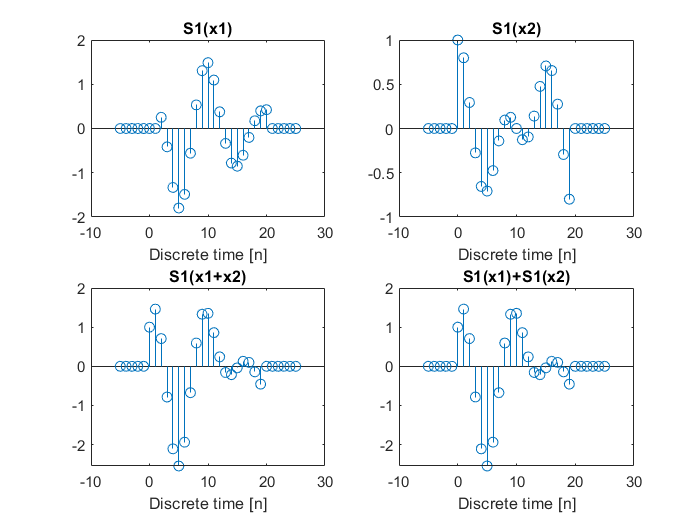

subplot(2,2,1)
stem(n,signal11)
title('S1(x1)')
xlabel('Discrete time [n]')


subplot(2,2,2)
stem(n,signal12)
title('S1(x2)')
xlabel('Discrete time [n]')


subplot(2,2,3)
stem(n,signal13)
title('S1(x1+x2)')
xlabel('Discrete time [n]')


subplot(2,2,4)
stem(n,signal01)
title('S1(x1)+S1(x2)')
xlabel('Discrete time [n]')

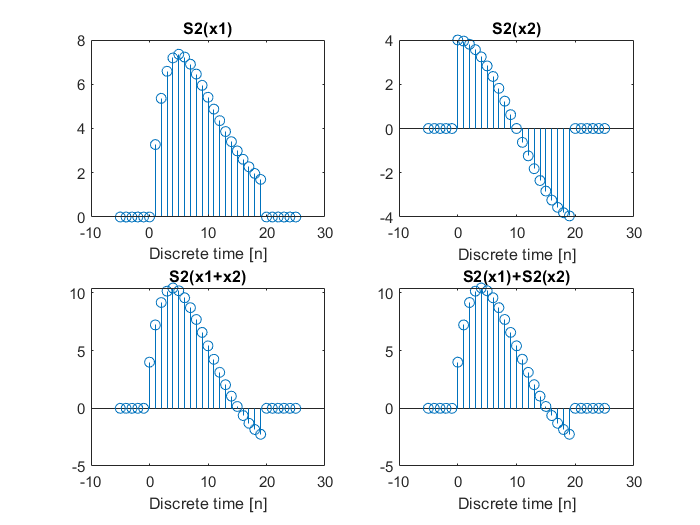

subplot(2,2,1)
stem(n,signal21)
title('S2(x1)')
xlabel('Discrete time [n]')


subplot(2,2,2)
stem(n,signal22)
title('S2(x2)')
xlabel('Discrete time [n]')


subplot(2,2,3)
stem(n,signal23)
title('S2(x1+x2)')
xlabel('Discrete time [n]')


subplot(2,2,4)
stem(n,signal02)
title('S2(x1)+S2(x2)')
xlabel('Discrete time [n]')

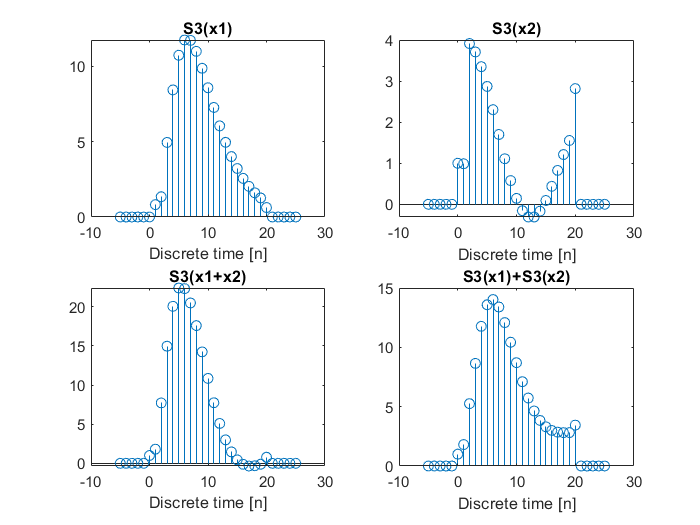


subplot(2,2,1)
stem(n,signal31)
title('S3(x1)')
xlabel('Discrete time [n]')


subplot(2,2,2)
stem(n,signal32)
title('S3(x2)')
xlabel('Discrete time [n]')


subplot(2,2,3)
stem(n,signal33)
title('S3(x1+x2)')
xlabel('Discrete time [n]')


subplot(2,2,4)
stem(n,signal03)
title('S3(x1)+S3(x2)')
xlabel('Discrete time [n]')

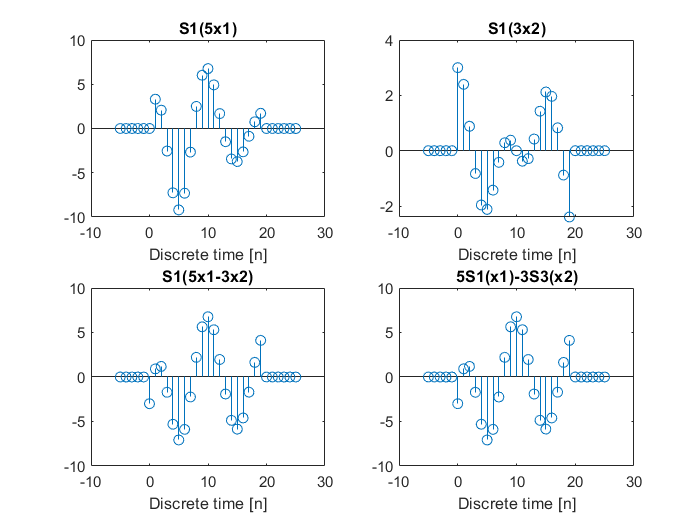

subplot(2,2,1)
stem(n,signal14)
title('S1(5x1)')
xlabel('Discrete time [n]')


subplot(2,2,2)
stem(n,signal15)
title('S1(3x2)')
xlabel('Discrete time [n]')


subplot(2,2,3)
stem(n,signal16)
title('S1(5x1-3x2)')
xlabel('Discrete time [n]')


subplot(2,2,4)
stem(n,signal04)
title('5S1(x1)-3S3(x2)')
xlabel('Discrete time [n]')

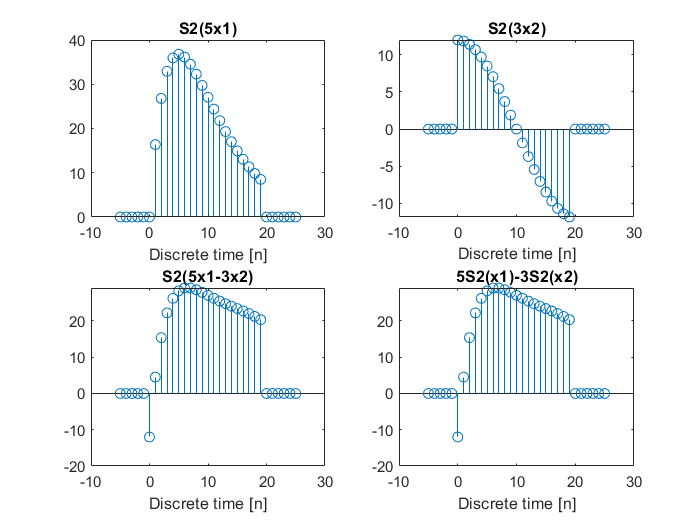

subplot(2,2,1)
stem(n,signal24)
title('S2(5x1)')
xlabel('Discrete time [n]')


subplot(2,2,2)
stem(n,signal25)
title('S2(3x2)')
xlabel('Discrete time [n]')


subplot(2,2,3)
stem(n,signal26)
title('S2(5x1-3x2)')
xlabel('Discrete time [n]')


subplot(2,2,4)
stem(n,signal05)
title('5S2(x1)-3S2(x2)')
xlabel('Discrete time [n]')

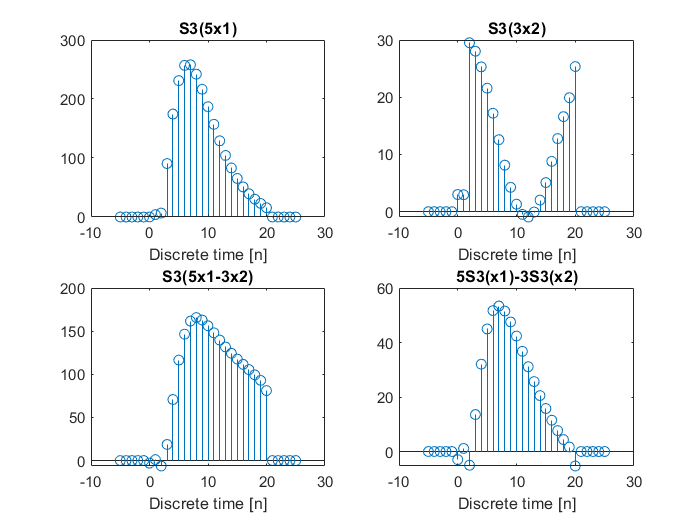

subplot(2,2,1)
stem(n,signal34)
title('S3(5x1)')
xlabel('Discrete time [n]')


subplot(2,2,2)
stem(n,signal35)
title('S3(3x2)')
xlabel('Discrete time [n]')


subplot(2,2,3)
stem(n,signal36)
title('S3(5x1-3x2)')
xlabel('Discrete time [n]')


subplot(2,2,4)
stem(n,signal06)
title('5S3(x1)-3S3(x2)')
xlabel('Discrete time [n]')

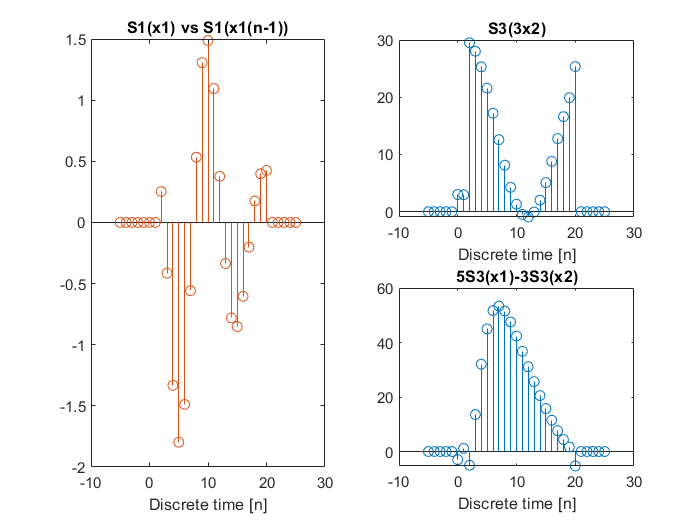

subplot(1,2,1)
stem(n,signal11)
hold on
stem(n,signal17)
title('S1(x1) vs S1(x1(n-1))')
xlabel('Discrete time [n]')

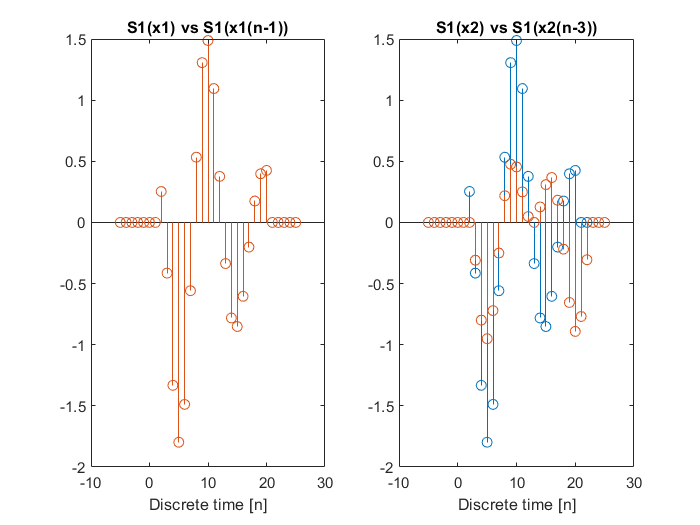



subplot(1,2,2)
stem(n,signal11)
hold on   
stem(n,signal18)
title('S1(x2) vs S1(x2(n-3))')
xlabel('Discrete time [n]')

function [y] = ofset(x,o)
    %Dezplaza un vector  un valor de ofset
    %   Detailed explanation goes here
    y=zeros(1, length(x));

        if o<0
            for i=1:(length(x)+o)
            y(i)=x(i-o);
            end
        end
        if o>0
            for i=(o+1):(length(x))
            y(i)=x(i-o);
            end
        end

end
function [y]=fx1(n)
    [y]=n.*exp(-0.2.*n).*(dtstep(n)-dtstep(n-20));
end
function [y]=fx2(n)
    [y]=cos(0.05*pi.*n).*(dtstep(n)-dtstep(n-20));
end
function [y]=s1(x,n)
    [y]=cos(0.2*pi.*n).*x;
end
function [y]=s2(x,n)
    [y]=x+3.*x;
end
function [y]=s3(x,n)
    [y]=x+3.*ofset(x,1).*ofset(x,2);
end
% function [y]=s3(x,n)
%     [y]=x+(3.*x(n-1));
% end


function dts= dtstep(n)
    dts = 1 * (floor(n) == n) .* (n >= 0);;
end
